依赖[统一实验分析作图v17.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

学习曲线

DataSetBas=TransferLearning.BasicTransferBehaviorDataSet;

统一实验分析作图v17.2.0已发布，<a href="https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases">立即更新</a>


SessionTableAL=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="声光水",Design="LightWater");
SessionTableAL.Group(:)="Transfer";
SessionTableLL=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="光声水",Design="LightWater");
SessionTableLL.Group(:)="Original";
[SummaryL,PValue]=UniExp.LearningSummarize([SessionTableAL;SessionTableLL]);

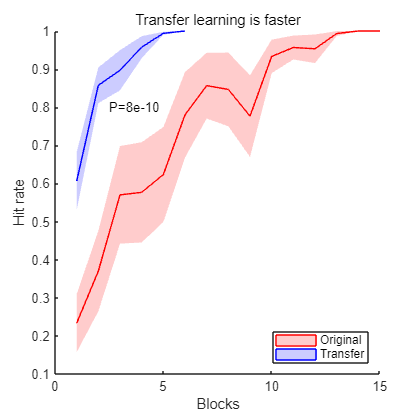

figure;
Colors=GlobalOptimization.ColorAllocate(2,[1,1,1;1,1,1]);
Patches=MATLAB.Graphics.MultiShadowedLines(SummaryL.MeanCurve,SummaryL.SemCurve,EdgeColors=Colors(1:2,:));
legend(Patches,SummaryL.Properties.RowNames,Location='southeast');title('Light-water');
xlabel('Blocks');
ylabel('Hit rate');
title('Transfer learning is faster');
text(2.5,0.8,sprintf('P=%.1g',PValue));
MATLAB.Graphics.FigureAspectRatio(1,1,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig1B.svg'),'-dsvg');